# Hierarchical Tree

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

X = readmatrix("./data/X.csv");
whos X

  Name        Size            Bytes  Class     Attributes

  X         124x4              3968  double              



## Task 1

You can use the `linkage` function to encode a tree of hierarchical clusters from a set of observations.

`Z` `=` `linkage``(``data``)`

Z = linkage(X);

## Task 2

You can use the `dendrogram` function to visualize the hierarchy of a binary cluster tree.

`dendrogram``(``linkages``)`

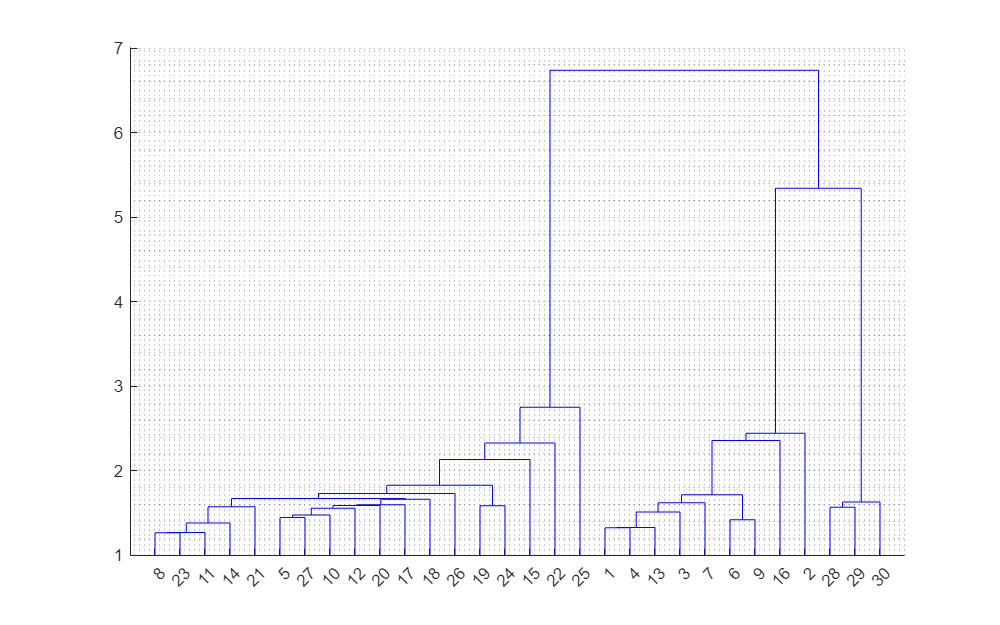

dendrogram(Z)
grid minor

## Task 3

You can modify the way that `linkage` computes the distance between clusters by passing an optional second input. For example, the `"ward"` method computes the inner squared distance using Ward's minimum variance algorithm.

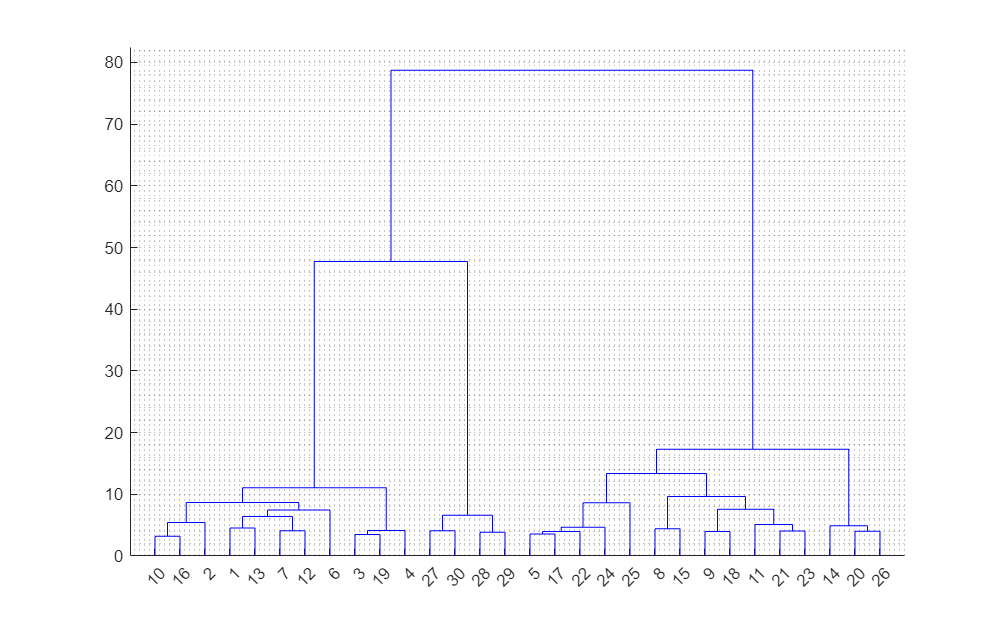

Zcomp = linkage(X, "ward");
dendrogram(Zcomp)
grid minor